Names_SAFT.Alkane = readtable("Unknown_SAFT.xlsx", "Sheet", "Alkane", "TextType","string");

Names_SAFT.Primary_Alcs = readtable("Unknown_SAFT.xlsx", "Sheet", "Primary Alcohol", "TextType","string");

Names_SAFT.Secondary_Alcs = readtable("Unknown_SAFT.xlsx", "Sheet", "Secondary Alcohol", "TextType","string");

Names_SAFT.Ester = readtable("Unknown_SAFT.xlsx", "Sheet", "Ester", "TextType","string");

Names_SAFT.All = readtable("Unknown_SAFT.xlsx", "Sheet", "All", "TextType","string");

MCM.SAFT = readtable("GR Hermanus (22796002).xlsx", "Sheet", "SAFT-VR MIE UNKNOWN", "TextType","string");

MCM.Alkane = readtable("GR Hermanus (22796002).xlsx", "Sheet", "MCM Alkane", "TextType","string");

MCM.Primary_alcs = readtable("GR Hermanus (22796002).xlsx", "Sheet", "MCM Primary Alcs", "TextType","string");

MCM.Secondary_alcs = readtable("GR Hermanus (22796002).xlsx", "Sheet", "MCM Secondary Alcs", "TextType","string");

MCM.Ester = readtable("GR Hermanus (22796002).xlsx", "Sheet", "MCM Ester", "TextType","string");

MCM.All = readtable("GR Hermanus (22796002).xlsx", "Sheet", "MCM All", "TextType","string");

mixtures = 67×1 string array
    "1-Butanol+1-Decanol"
    "1-Butanol+1-Hexanol"
    "1-Butanol+1-Pentanol"
    "1-Butanol+1-Propanol"
    "1-Decanol+1-Hexanol"
    "1-Decanol+1-Propanol"
    "1-Decanol+Butyl acetate"
    "1-Decanol+Propan-2-ol"
    "1-Hexanol+1-Pentanol"
    "1-Hexanol+Butyl acetate"
    "1-Octanol+1-Butanol"
    "1-Octanol+1-Decanol"
    "1-Octanol+1-Hexanol"
    "1-Octanol+1-Propanol"
    "1-Octanol+Butyl acetate"
    "1-Octanol+Pentane"
    "1-Pentanol+1-Propanol"
    "1-Pentanol+Decane"
    "1-Pentanol+Octane"
    "1-Pentanol+Pentane"
    "1-Pentanol+Propan-2-ol"
    "1-Propanol+Decane"
    "1-Propanol+Hexane"
    "Butan-2-ol+1-Butanol"
    "Butan-2-ol+1-Decanol"
    "Butan-2-ol+1-Hexanol"
    "Butan-2-ol+1-Octanol"
    "Butan-2-ol+1-Pentanol"
    "Butan-2-ol+1-Propanol"
    "Butan-2-ol+Hexane"


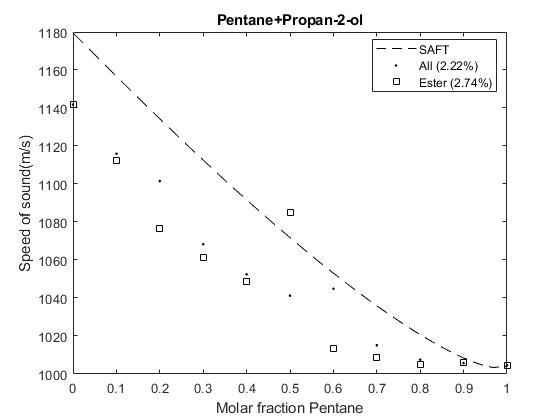

formatting = ["--k", ".k", "sk", "dk", "^k", "vk"]; 
folder = "C:\Users\Garren\Documents\FYP\Code_and_excel_file\Effect of adding functional groups";
for i = 1:4
    
    if i == 1
        mixtures = Names_SAFT.Alkane.Mixture;
        newfolder = folder+"\Alkane";
        for j = 1:numel(mixtures)
            index1 = (MCM.SAFT.Component1+"+"+MCM.SAFT.Component2) == mixtures(j);
            comp1 = MCM.SAFT.MolarComposition1(index1);
            index2 = (MCM.All.Component1+"+"+MCM.All.Component2) == mixtures(j);
            comp2 = MCM.All.MolarComposition1(index2);
            index3 = (MCM.Ester.Component1+"+"+MCM.Ester.Component2) == mixtures(j);
            comp3 = MCM.Ester.MolarComposition1(index3);
            index4 = (MCM.Secondary_alcs.Component1+"+"+MCM.Secondary_alcs.Component2) == mixtures(j);
            comp4 = MCM.Secondary_alcs.MolarComposition1(index4);
            index5 = (MCM.Primary_alcs.Component1+"+"+MCM.Primary_alcs.Component2) == mixtures(j);
            comp5 = MCM.Primary_alcs.MolarComposition1(index5);
            index6 = (MCM.Alkane.Component1+"+"+MCM.Alkane.Component2) == mixtures(j);
            comp6 = MCM.Alkane.MolarComposition1(index6);
            
            if sum(index1) == 0
                index1 = (MCM.SAFT.Component2+"+"+MCM.SAFT.Component1) == mixtures(j);
                comp1 = 1 - MCM.SAFT.MolarComposition1(index1);
            end
            
            if sum(index2) == 0
                index2 = (MCM.All.Component2+"+"+MCM.All.Component1) == mixtures(j);
                comp2 = 1 - MCM.All.MolarComposition1(index2);
                index3 = (MCM.Ester.Component2+"+"+MCM.Ester.Component1) == mixtures(j);
                comp3 = 1 - MCM.Ester.MolarComposition1(index3);
                index4 = (MCM.Secondary_alcs.Component2+"+"+MCM.Secondary_alcs.Component1) == mixtures(j);
                comp4 = 1 - MCM.Secondary_alcs.MolarComposition1(index4);
                index5 = (MCM.Primary_alcs.Component2+"+"+MCM.Primary_alcs.Component1) == mixtures(j);
                comp5 = 1 - MCM.Primary_alcs.MolarComposition1(index5);
                index6 = (MCM.Alkane.Component2+"+"+MCM.Alkane.Component1) == mixtures(j);
                comp6 = 1 - MCM.Alkane.MolarComposition1(index6);
            end
            sop1 = MCM.SAFT.SpeedOfSound_m_s_(index1);
            sop2 = MCM.All.SpeedOfSound_m_s_(index2);
            sop3 = MCM.Ester.SpeedOfSound_m_s_(index3);
            sop4 = MCM.Secondary_alcs.SpeedOfSound_m_s_(index4);
            sop5 = MCM.Primary_alcs.SpeedOfSound_m_s_(index5);
            sop6 = MCM.Alkane.SpeedOfSound_m_s_(index6);
            
            subplot(1, 1, 1)
            plot(comp1, sop1, formatting(1)); hold on
            plot(comp2, sop2, formatting(2));
            plot(comp3, sop3, formatting(3));
            plot(comp4, sop4, formatting(4));
            plot(comp5, sop5, formatting(5));
            plot(comp6, sop6, formatting(6));
            title([mixtures(j)]);
            xlabel(["Molar fraction "+unique(MCM.SAFT.Component1(index1))]); ylabel("Speed of sound(m/s)")
            legend("SAFT", sprintf("All (%.2f%%)", Names_SAFT.All.Average_AAD(Names_SAFT.All.Mixture == mixtures(j))), ...
                sprintf("Ester (%.2f%%)", Names_SAFT.Ester.Average_AAD(Names_SAFT.Ester.Mixture == mixtures(j))), ...
                sprintf("Secondary Alcs (%.2f%%)", Names_SAFT.Secondary_Alcs.Average_AAD(Names_SAFT.Secondary_Alcs.Mixture == mixtures(j))), ...
                sprintf("Primary Alcs (%.2f%%)", Names_SAFT.Primary_Alcs.Average_AAD(Names_SAFT.Primary_Alcs.Mixture == mixtures(j))), ...
                sprintf("Alkane (%.2f%%)", Names_SAFT.Alkane.Average_AAD(Names_SAFT.Alkane.Mixture == mixtures(j))),...
                "Location","best"); hold off
            filename = mixtures(j)+".jpeg";
            f = getframe(gcf);
            imwrite(f.cdata, fullfile(newfolder, filename));
        end
        
    elseif i == 2
        mixtures = Names_SAFT.Primary_Alcs.Mixture;
        newfolder = folder+"\Primary alcohols";
        for j = 1:numel(mixtures)
            index1 = (MCM.SAFT.Component1+"+"+MCM.SAFT.Component2) == mixtures(j);
            comp1 = MCM.SAFT.MolarComposition1(index1);
            index2 = (MCM.All.Component1+"+"+MCM.All.Component2) == mixtures(j);
            comp2 = MCM.All.MolarComposition1(index2);
            index3 = (MCM.Ester.Component1+"+"+MCM.Ester.Component2) == mixtures(j);
            comp3 = MCM.Ester.MolarComposition1(index3);
            index4 = (MCM.Secondary_alcs.Component1+"+"+MCM.Secondary_alcs.Component2) == mixtures(j);
            comp4 = MCM.Secondary_alcs.MolarComposition1(index4);
            index5 = (MCM.Primary_alcs.Component1+"+"+MCM.Primary_alcs.Component2) == mixtures(j);
            comp5 = MCM.Primary_alcs.MolarComposition1(index5);
            
            if sum(index1) == 0
                index1 = (MCM.SAFT.Component2+"+"+MCM.SAFT.Component1) == mixtures(j);
                comp1 = 1 - MCM.SAFT.MolarComposition1(index1);
            end
            
            if sum(index2) == 0
                index2 = (MCM.All.Component2+"+"+MCM.All.Component1) == mixtures(j);
                comp2 = 1 - MCM.All.MolarComposition1(index2);
                index3 = (MCM.Ester.Component2+"+"+MCM.Ester.Component1) == mixtures(j);
                comp3 = 1 - MCM.Ester.MolarComposition1(index3);
                index4 = (MCM.Secondary_alcs.Component2+"+"+MCM.Secondary_alcs.Component1) == mixtures(j);
                comp4 = 1 - MCM.Secondary_alcs.MolarComposition1(index4);
                index5 = (MCM.Primary_alcs.Component2+"+"+MCM.Primary_alcs.Component1) == mixtures(j);
                comp5 = 1 - MCM.Primary_alcs.MolarComposition1(index5);
                
            end
            sop1 = MCM.SAFT.SpeedOfSound_m_s_(index1);
            sop2 = MCM.All.SpeedOfSound_m_s_(index2);
            sop3 = MCM.Ester.SpeedOfSound_m_s_(index3);
            sop4 = MCM.Secondary_alcs.SpeedOfSound_m_s_(index4);
            sop5 = MCM.Primary_alcs.SpeedOfSound_m_s_(index5);
            
            subplot(1, 1, 1)
            plot(comp1, sop1, formatting(1)); hold on
            plot(comp2, sop2, formatting(2));
            plot(comp3, sop3, formatting(3));
            plot(comp4, sop4, formatting(4));
            plot(comp5, sop5, formatting(5));
            title([mixtures(j)]);
            xlabel(["Molar fraction "+unique(MCM.SAFT.Component1(index1))]); ylabel("Speed of sound(m/s)")
            legend("SAFT", sprintf("All (%.2f%%)", Names_SAFT.All.Average_AAD(Names_SAFT.All.Mixture == mixtures(j))), ...
                sprintf("Ester (%.2f%%)", Names_SAFT.Ester.Average_AAD(Names_SAFT.Ester.Mixture == mixtures(j))), ...
                sprintf("Secondary Alcs (%.2f%%)", Names_SAFT.Secondary_Alcs.Average_AAD(Names_SAFT.Secondary_Alcs.Mixture == mixtures(j))), ...
                sprintf("Primary Alcs (%.2f%%)", Names_SAFT.Primary_Alcs.Average_AAD(Names_SAFT.Primary_Alcs.Mixture == mixtures(j))), ...
                "Location","best"); hold off
            filename = mixtures(j)+".jpeg";
            f = getframe(gcf);
            imwrite(f.cdata, fullfile(newfolder, filename));
        end
        
    elseif i == 3
        mixtures = Names_SAFT.Secondary_Alcs.Mixture;
        newfolder = folder+"\Secondary alcohols";
        for j = 1:numel(mixtures)
            index1 = (MCM.SAFT.Component1+"+"+MCM.SAFT.Component2) == mixtures(j);
            comp1 = MCM.SAFT.MolarComposition1(index1);
            index2 = (MCM.All.Component1+"+"+MCM.All.Component2) == mixtures(j);
            comp2 = MCM.All.MolarComposition1(index2);
            index3 = (MCM.Ester.Component1+"+"+MCM.Ester.Component2) == mixtures(j);
            comp3 = MCM.Ester.MolarComposition1(index3);
            index4 = (MCM.Secondary_alcs.Component1+"+"+MCM.Secondary_alcs.Component2) == mixtures(j);
            comp4 = MCM.Secondary_alcs.MolarComposition1(index4);
            
            if sum(index1) == 0
                index1 = (MCM.SAFT.Component2+"+"+MCM.SAFT.Component1) == mixtures(j);
                comp1 = 1 - MCM.SAFT.MolarComposition1(index1);
            end
            
            if sum(index2) == 0
                index2 = (MCM.All.Component2+"+"+MCM.All.Component1) == mixtures(j);
                comp2 = 1 - MCM.All.MolarComposition1(index2);
                index3 = (MCM.Ester.Component2+"+"+MCM.Ester.Component1) == mixtures(j);
                comp3 = 1 - MCM.Ester.MolarComposition1(index3);
                index4 = (MCM.Secondary_alcs.Component2+"+"+MCM.Secondary_alcs.Component1) == mixtures(j);
                comp4 = 1 - MCM.Secondary_alcs.MolarComposition1(index4);
                
            end
            sop1 = MCM.SAFT.SpeedOfSound_m_s_(index1);
            sop2 = MCM.All.SpeedOfSound_m_s_(index2);
            sop3 = MCM.Ester.SpeedOfSound_m_s_(index3);
            sop4 = MCM.Secondary_alcs.SpeedOfSound_m_s_(index4);
            
            subplot(1, 1, 1)
            plot(comp1, sop1, formatting(1)); hold on
            plot(comp2, sop2, formatting(2));
            plot(comp3, sop3, formatting(3));
            plot(comp4, sop4, formatting(4));

            title([mixtures(j)]);
            xlabel(["Molar fraction "+unique(MCM.SAFT.Component1(index1))]); ylabel("Speed of sound(m/s)")
           legend("SAFT", sprintf("All (%.2f%%)", Names_SAFT.All.Average_AAD(Names_SAFT.All.Mixture == mixtures(j))), ...
                sprintf("Ester (%.2f%%)", Names_SAFT.Ester.Average_AAD(Names_SAFT.Ester.Mixture == mixtures(j))), ...
                sprintf("Secondary Alcs (%.2f%%)", Names_SAFT.Secondary_Alcs.Average_AAD(Names_SAFT.Secondary_Alcs.Mixture == mixtures(j))), ...
                "Location","best"); hold off
            filename = mixtures(j)+".jpeg";
            f = getframe(gcf);
            imwrite(f.cdata, fullfile(newfolder, filename));
        end
        
    elseif i == 4
        mixtures = Names_SAFT.Ester.Mixture
        newfolder = folder+"\Ester";
        for j = 1:numel(mixtures)
            index1 = (MCM.SAFT.Component1+"+"+MCM.SAFT.Component2) == mixtures(j);
            comp1 = MCM.SAFT.MolarComposition1(index1);
            index2 = (MCM.All.Component1+"+"+MCM.All.Component2) == mixtures(j);
            comp2 = MCM.All.MolarComposition1(index2);
            index3 = (MCM.Ester.Component1+"+"+MCM.Ester.Component2) == mixtures(j);
            comp3 = MCM.Ester.MolarComposition1(index3);
            
            if sum(index1) == 0
                index1 = (MCM.SAFT.Component2+"+"+MCM.SAFT.Component1) == mixtures(j);
                comp1 = 1 - MCM.SAFT.MolarComposition1(index1);
            end
            
            if sum(index2) == 0
                index2 = (MCM.All.Component2+"+"+MCM.All.Component1) == mixtures(j);
                comp2 = 1 - MCM.All.MolarComposition1(index2);
                index3 = (MCM.Ester.Component2+"+"+MCM.Ester.Component1) == mixtures(j);
                comp3 = 1 - MCM.Ester.MolarComposition1(index3);
                
            end
            sop1 = MCM.SAFT.SpeedOfSound_m_s_(index1);
            sop2 = MCM.All.SpeedOfSound_m_s_(index2);
            sop3 = MCM.Ester.SpeedOfSound_m_s_(index3);
            
            subplot(1, 1, 1)
            plot(comp1, sop1, formatting(1)); hold on
            plot(comp2, sop2, formatting(2));
            plot(comp3, sop3, formatting(3));

            title([mixtures(j)]);
            xlabel(["Molar fraction "+unique(MCM.SAFT.Component1(index1))]); ylabel("Speed of sound(m/s)")
            legend("SAFT", sprintf("All (%.2f%%)", Names_SAFT.All.Average_AAD(Names_SAFT.All.Mixture == mixtures(j))), ...
                sprintf("Ester (%.2f%%)", Names_SAFT.Ester.Average_AAD(Names_SAFT.Ester.Mixture == mixtures(j))), ...
                "Location","best"); hold off
            filename = mixtures(j)+".jpeg";
            f = getframe(gcf);
            imwrite(f.cdata, fullfile(newfolder, filename));
        end
        
    end
    
end